M130 Lab 6

Start by checking the image properties of your assigned image and loading it into MATLAB

%Load your image, these are 2D images (1 point)
info = imfinfo('2D_Image_8.tif')

info = struct with fields:
                     Filename: 'C:\Users\wangs\Downloads\2D_Image_8.tif'
                  FileModDate: '18-May-2023 09:58:12'
                     FileSize: 362188
                       Format: 'tif'
                FormatVersion: []
                        Width: 696
                       Height: 520
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: 268
              SamplesPerPixel: 1
                 RowsPerStrip: 520
              StripByteCounts: 361920
                  XResolution: []
                  YResolution: []
               ResolutionUnit: 'Inch'
                     Colormap: []
          PlanarConfiguration: 'Chunky'
                    Ti

img = imread('2D_Image_8.tif')

img = 520×696 uint8 matrix
   29   31   31   32   32   31   30   29   28   27   26   25   23   24   21   22   21   20   20   19   19   21   20   19   20   20   21   22   23   23   24   26   28   34   37   42   45   49   49   51   58   59   60   59   64   62   60   57   58   57
   32   35   38   40   40   40   40   36   33   29   28   25   25   24   23   23   22   21   21   20   20   19   20   20   20   21   20   21   23   23   24   26   28   31   37   42   45   46   49   50   53   56   57   61   64   62   55   59   59   57
   37   41   44   52   54   53   51   46   39   33   29   28   27   26   24   22   22   21   21   20   21   20   21   20   20   21   22   22   22   22   25   25   27   29   35   39   42   46   46   47   51   54   56   57   60   60   58   57   58   61
   42   50   55   59   60   59   59   55   49   38   33   30   28   26   26   24   23   22   22   21   20   21   21   20   20   21   21   21   21   24   23   25   24   27   31   36   41   44   46   49   51   53   55   56

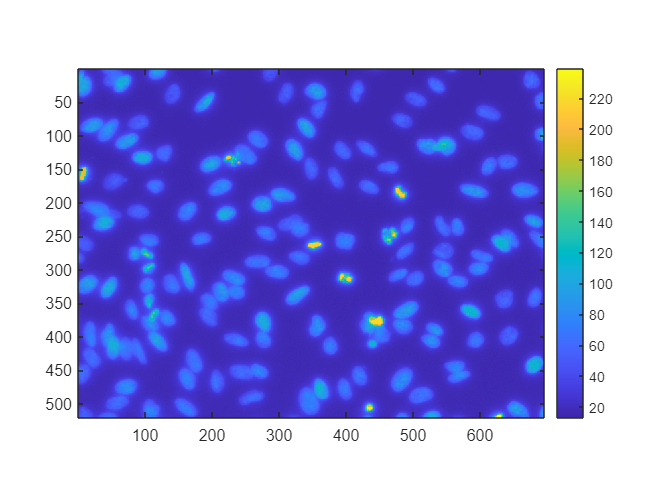

imagesc(img)
colorbar 
axis image 

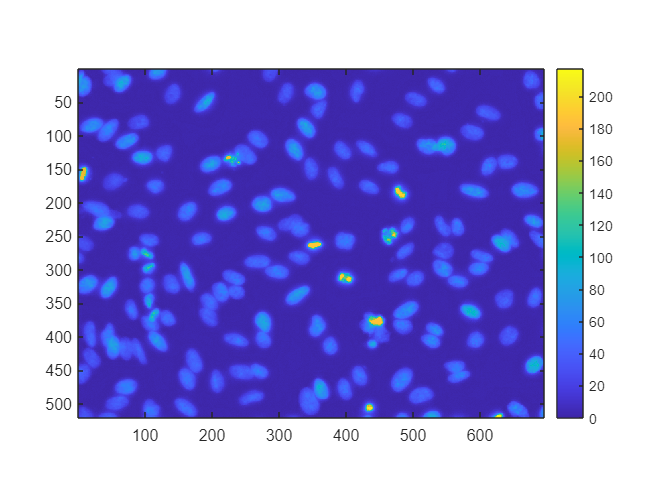

%Image processing tasks (4 points):
%Perform background subtraction by morphological opening. Pick a large
%radius for the strel function that would extend outside of any objects or
%clumps of objects in the foreground    


bg = imopen(img,strel('disk',20)); %picking a large strel 
img_bg = img-bg; %background subtraction step 
imagesc(img_bg)
colorbar
axis image

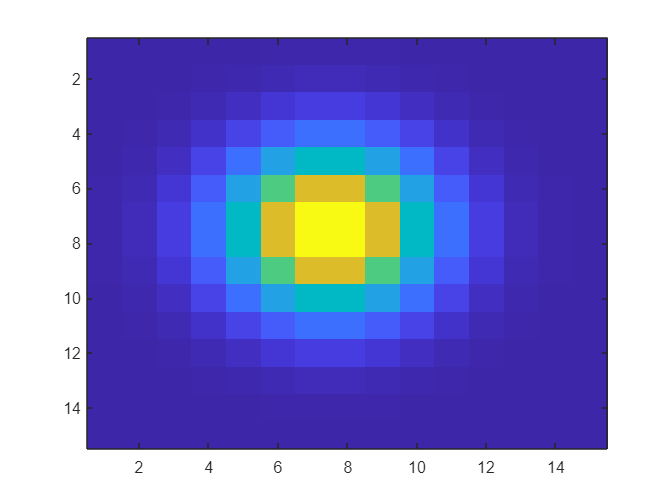

%Given the image, decide whether you want to attempt the watershed using
%the distance transform or the Laplacian.
%If using the distance transform, denoise using a Gaussian blur
%If using the LoG, calculate the Laplacian kernel, guess and check to find
%a value for c that gives you a clear minimum near the middle of each
%object

%I will be using the distance transform

m = 15; %denoising using Gaussian blur 
n = 15;
gaussian = zeros(m,n);
c = 2; 
for x=1:n
    for y=1:m
        sq_dist = (x-n/2)^2 + (y-m/2)^2; 
        gaussian(y,x) = exp(-1*sq_dist/(2*c*c)); 
    end
end
gaussian = gaussian./sum(gaussian(:)); 
imagesc(gaussian)

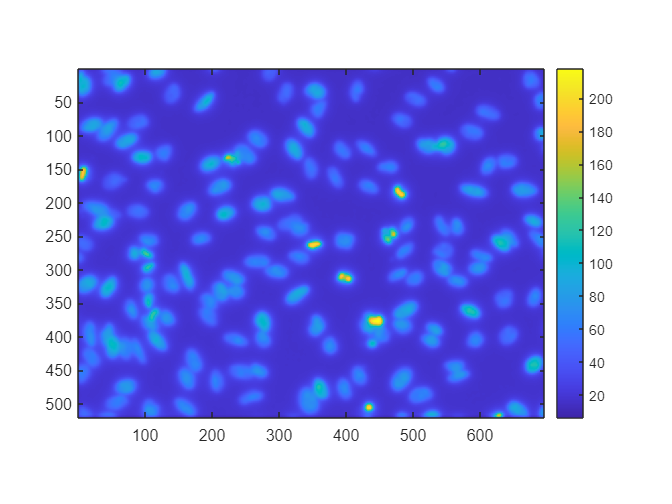

img_blur = conv2(img,gaussian,'same');
imagesc(img_blur)
colorbar
axis image 


disp(['The Laplacian transform requires us to define cell size, ' ...
    'by measuring the pixel values. In that case, images with similar cell size will be most fitting.' ...
    'However, non-uniform cell sizes such as smaller radius cells can not fit in this universality rule'])

The Laplacian transform requires us to define cell size, by measuring the pixel values. In that case, images with similar cell size will be most fitting.However, non-uniform cell sizes such as smaller radius cells can not fit in this universality rule


disp('The distance transform does not require similar cell size, for it takes measurements relative to other neighboring cells.')

The distance transform does not require similar cell size, for it takes measurements relative to other neighboring cells.


disp('We will be using the distance transform to attempt the watershed')

We will be using the distance transform to attempt the watershed



%Perform Intensity Thresholding
%Test manual, Otsu's and adaptive thresholding approaches and pick the one
%you like best to use for the rest of the lab
disp('Manual thresholding below')

Manual thresholding below


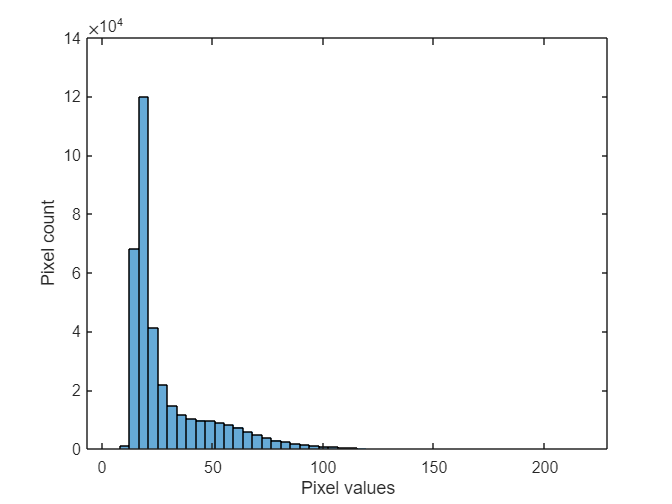

histogram(double(img_blur(:)), 50)
xlabel('Pixel values')
ylabel('Pixel count')

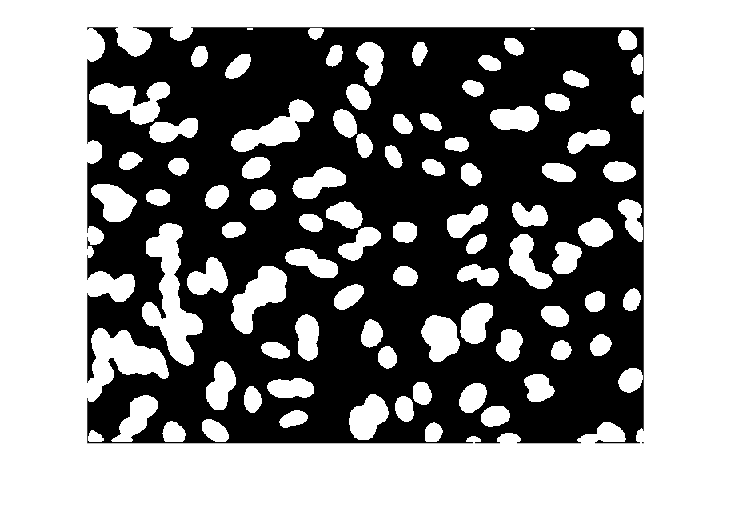

thresh = 35; %this is the threshold because majority of the pixels are less than 35
manual = img_blur > thresh; 
imshow(manual)

disp('Otsu thresholding below')

Otsu thresholding below


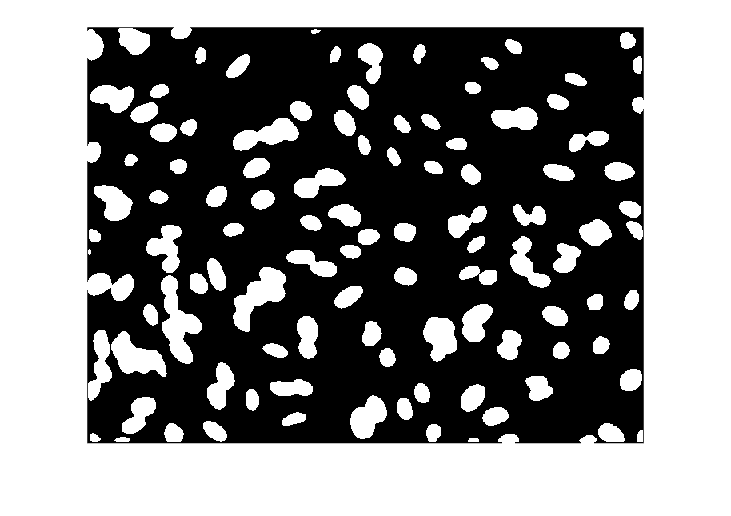

otsu = imbinarize(uint8(img_blur), "global");
imshow(otsu)

disp('Adaptive method below')

Adaptive method below


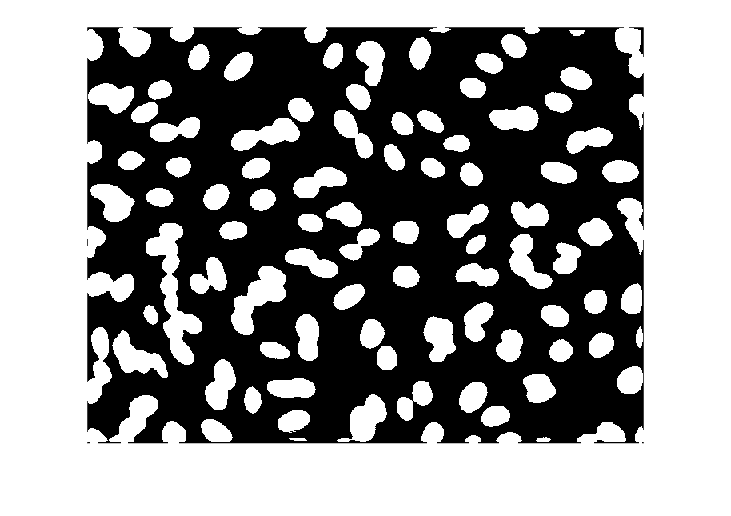

adaptive = imbinarize(uint16(img_blur),"adaptive");
imshow(adaptive)

disp('It looks like the adaptive method does intensity thresholding the best, we will use it for the rest of the lab')

It looks like the adaptive method does intensity thresholding the best, we will use it for the rest of the lab


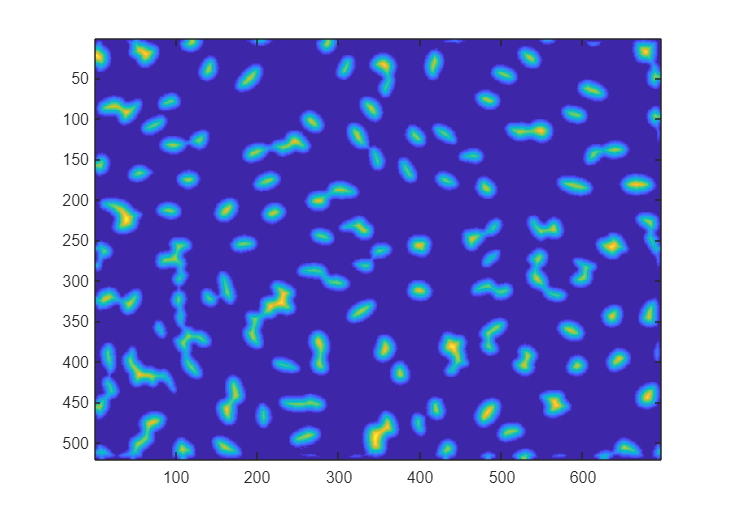

D = bwdist(~adaptive); 
imagesc(D);

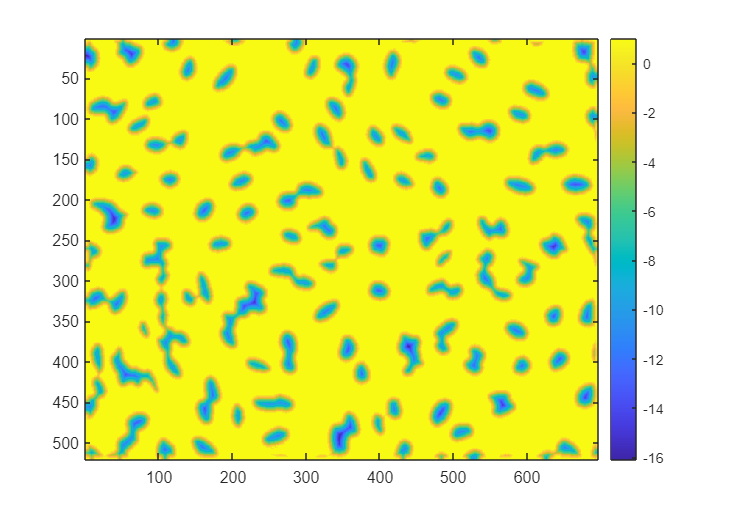

D = imcomplement(D);
imagesc(D);
colorbar

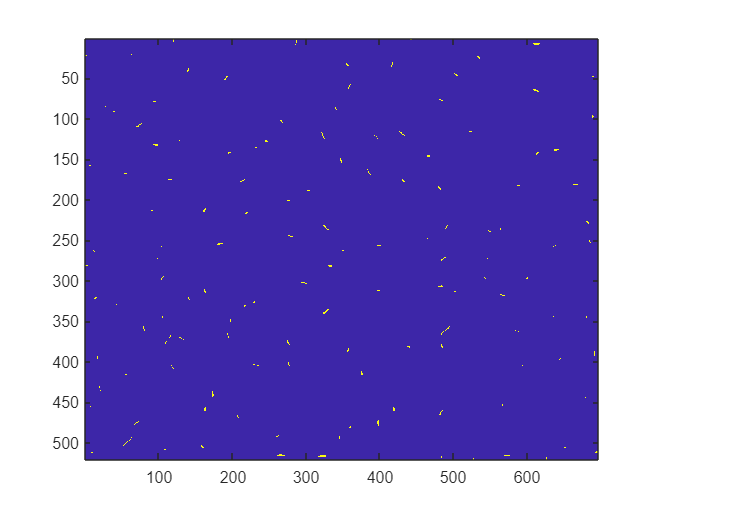

minima = imextendedmin(D,0.5);
imagesc(minima);

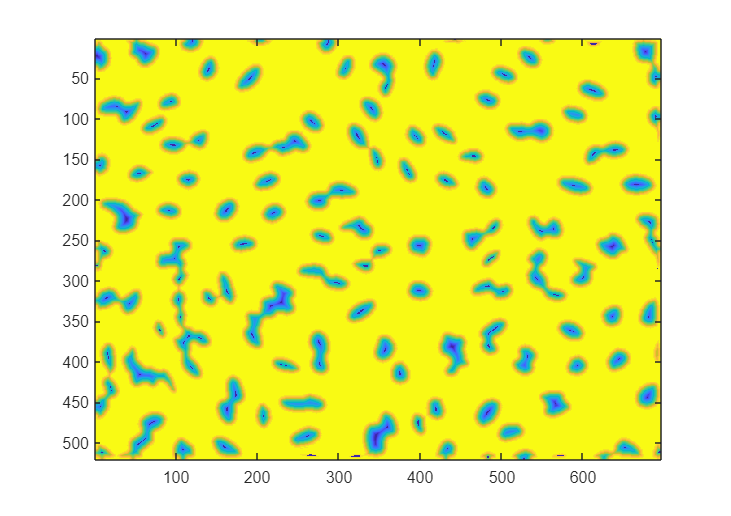

D = imimposemin(D, minima);
imagesc(D)

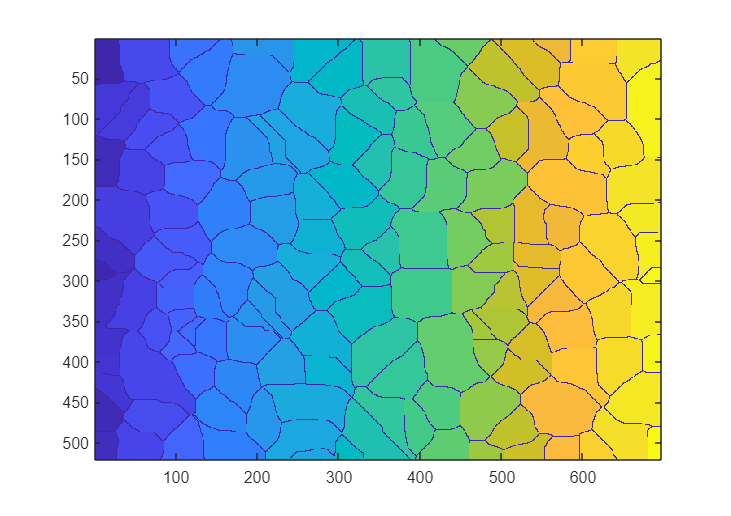

%Further refine the segmentation using the watershed transform (3 points)

W = watershed(D);
imagesc(W)

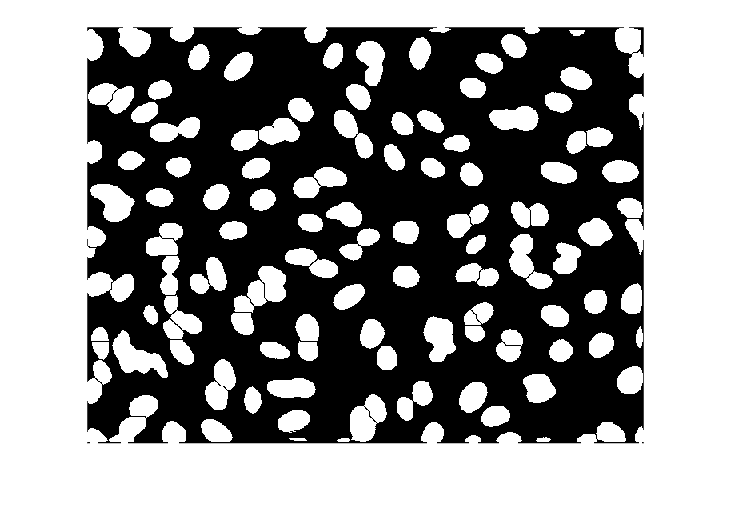

BW = adaptive;
BW(W==0)=0;
imshow(BW)

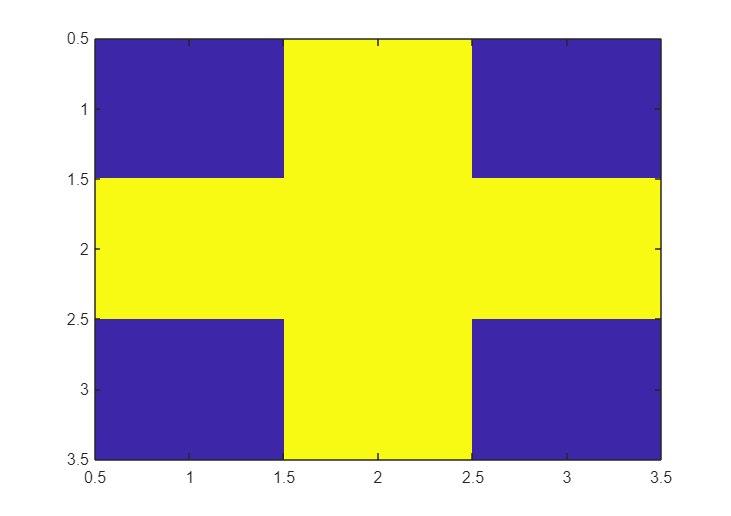

%Clean up the segmentation by mathematical morphology 

SE = strel('disk',1);
imagesc(SE.Neighborhood)

disp(['the radius of the structuring element needs to be larger than any foreground object.' ...
    ' Making it too big is usually fine, making it too small can be disastrous'])

the radius of the structuring element needs to be larger than any foreground object. Making it too big is usually fine, making it too small can be disastrous


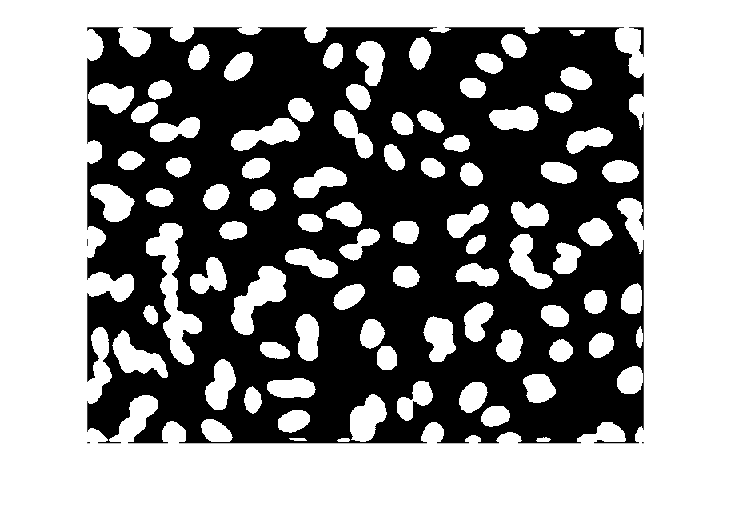

BW1 = bwareaopen(BW,50); % use bwareaopen to get rid of tiny isolated clusters of pixels 
%first shrink the image, then do dilation to expand the image. 
BW1 = imclose(BW1, SE);
imshow(BW1)

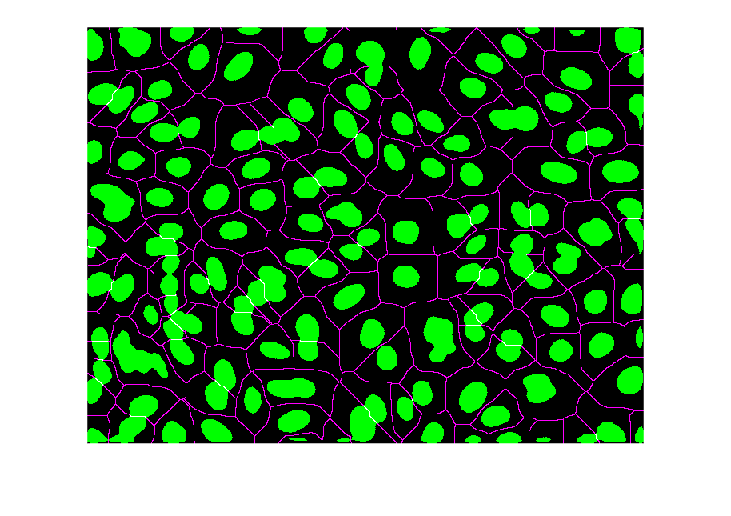


boundaries = W==0;
imshowpair(BW1,boundaries)

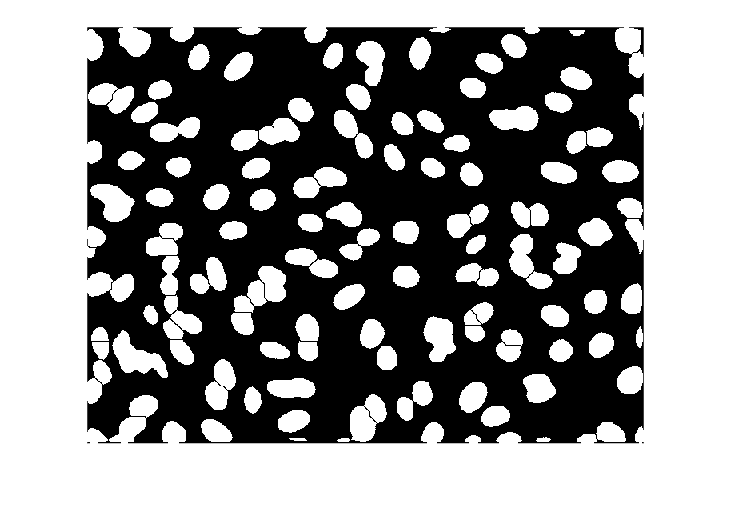

bw2 = BW1;
bw2(boundaries) = 0;
imshow(bw2)

%Discuss the results, did the watershed improve segmentation quality at
%all? (1 point)
% The watershed improved segmentation quality by getting rid of basically
% all of the background. However, after clean up we see some cells are
% sliced in half. When we tuned the imextendedmin to 0.5, it seemed to have
% adjusted to the local minima. The image segmentation does not vary upon
% increasing imextendedmin or decreasing imextendedmin. 


Share some feedback, what's working for you? what's not working for you? what concepts are you struggling with the most? (1 point)

So far, everything seem to be working for me. I am a little confused on the ordering of the questions, which seems to be misleading. The concept I am struggling the most is perhaps the other method of LoG, which I didn't get to use for this lab. 